Calculate Lift and Drag forces.

L = 0.5*density*v.^2.*S*Cl;

Unrecognized function or variable 'density'.

D = 0.5*density*v.^2.*S*CD;

Define aspect ratio(AR).

b: span  c: mean aerodynamic chord  S: surface area

AR = b^2./S;

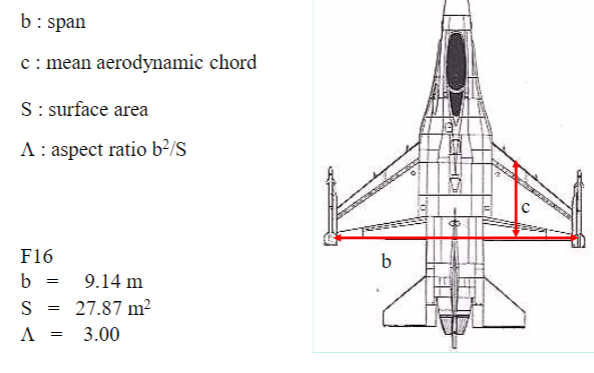

Mean aerodynamic chord (c_mac):

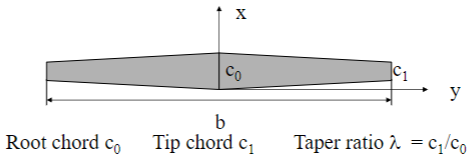


$$c=\frac{\int_{-\frac{b}{2}}^{\frac{b}{2}} {c\left(y\right)}^2 \;\textrm{dy}}{S}$$


%example
syms c c0 c1 lamda y b %define variable
lamda = c1/c0; %taper ratio
c = c0*(1-2*(1-lamda)*(y/b));%depending on wings shape

c_mac = int(c.^2,y,b/2,-b/2)./((c1+c0)*b./4);%matlab indefinite integral

Location of the mean aerodynamic chord (y):


$$y=\frac{\int_0^{\frac{b}{2}} {c\left(y\right)y} \;\textrm{dy}}{\frac{S}{2}}$$


y_mac = int(c*y,y,b/2,0)./((c1+c0)*b./8);

Wing Loading:

WL = L/S;
%lift = weight for level flight
WL = W/S;

## **Equations of motion for aircraft (point mass)**

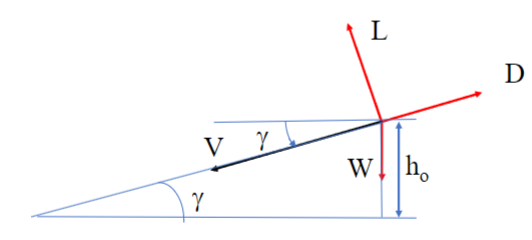

Equations of motions ($\gamma$ is negative for glide):


$$\begin{array}{l}
m\;\frac{\textrm{dV}}{\textrm{dt}}=T-D-W\;\sin \;\gamma \\
\textrm{mV}\frac{\;d\gamma }{\textrm{dt}}=L-W\;\cos \gamma \\
\frac{\textrm{dx}}{\textrm{dt}}=V\;\cos \gamma \\
\frac{\textrm{dh}}{\textrm{dt}}=V\;\sin \gamma 
\end{array}$$


For gliding, T = 0


$$m\;\frac{\textrm{dV}}{\textrm{dt}}\;=\;D-W\;\sin \;\gamma$$


Example 1: 

*Steady gliding flight:*


$$\begin{array}{l}
\frac{\textrm{dV}}{\textrm{dt}}=0\\
\frac{\;d\gamma }{\textrm{dt}}=0
\end{array}$$


*Therefore:*


$$\begin{array}{l}
D=-W\;\sin \gamma \\
L=-W\;\cos \gamma \\
\frac{D}{L}=-\tan \gamma 
\end{array}$$


Define aerodynamic efficiency, relationship between CD, CL


$$E=\frac{L}{D}=\frac{\textrm{CL}}{\textrm{CD}}$$



$$\begin{array}{l}
\textrm{CD}={\textrm{CD}}_0 \;+K\;{\textrm{CL}}^2 \\
K=\;\frac{1}{\pi \;\varepsilon \;\textrm{AR}}\;
\end{array}$$
 

$\varepsilon$: Oswald efficiency factor 0.8 - 1.0

Maximum efficiency can be found when plotting CL/CD over CL

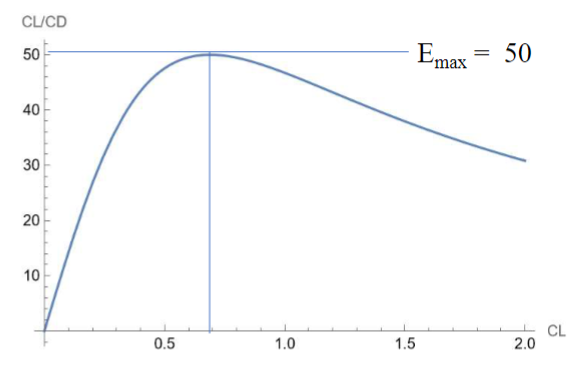

### Level Flight (G02EX2)

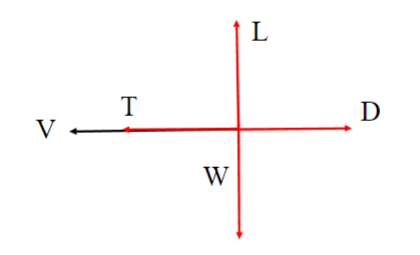

Trust is a function of altitude and velocity, T(h, V). Density is a function of altitude, p(h). 

Key in aircraft's parameters.

S = 17.1;
mass = 1248.5;
CLmax = 3; %Maximum CL of aircraft
W = mass * 9.81;
pset = 0.5; %power setting, determine Thrust equation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

fsolve function: 

input one: function that contains n equations with n variables.

input two: initial guess, each of the n variables.

In this case, two equations and two variables, CL and V. Initial guess is [CLguess, Vguess].

**The below codes find the range of CL, Velocity that aircraft operate at sea level (h=0), known as trim CL, V. **

guess1 = [0.1, 50];
sol1 = fsolve(@(var) findclsea(var, 0), guess1);
CLguess1 = sol1(1);
Vguess1 = sol1(2); 

disp(['CL1 at sea level = ', num2str(CLguess1)]);
disp(['V1 at sea level = ', num2str(Vguess1)]);

guess2 = [2, 10];
sol2 = fsolve(@(var) findclsea(var, 0), guess2);
CLguess2 = sol2(1);
Vguess2 = sol2(2); 

disp(['CL2 at sea level = ', num2str(CLguess2)]);
disp(['V2 at sea level = ', num2str(Vguess2)]);

function F =  findclsea(var, h)

clg = var(1);
vg = var(2);

S = 17.1;
mass = 1248.5;
pset = 0.5; %0.3 0.7
W = mass * 9.81;
Tsl = 288;
T = Tsl - 6.51 * h;
%Speed of sound
a = sqrt(1.4 * 287 * T);

%Calculating the Thrust on sea level
c0 = 7106.47 - 0.781351 * h;
c1 = -2094.99 + 0.216186 * h;
c2 = -3638.48 + 0.45727 * h;
T = pset * (c0 + (vg/a) * (c1 + c2 * (vg/a)));

%Equations to solve
F(1) = 0.5*clg*P2(h/1000)*vg^2*S - W;
F(2) = 0.5*(0.036 + 0.06 * clg^2)*P2(h/1000)*vg^2*S - T;

end 

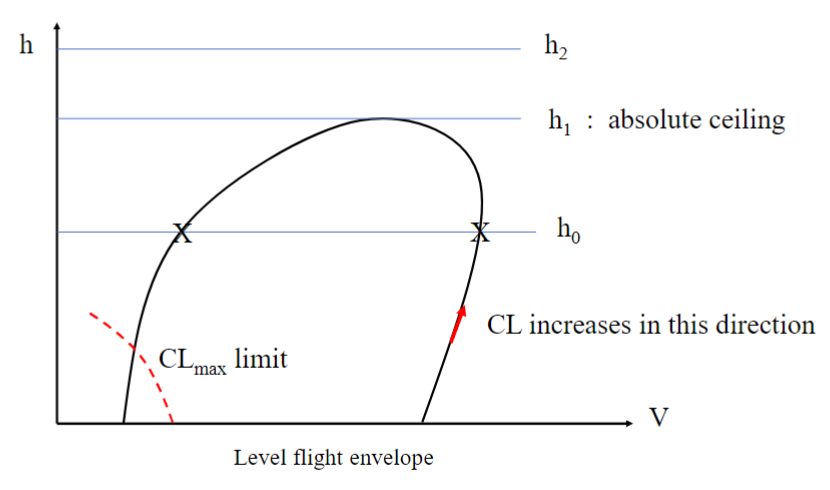

Increasing altitude will narrow the CL range. Gradually increase h will increase CL, until it meets CLmax. Then can find Absolute ceiling (Maximum Altitude).

Try every CL value and find corresponding Velocity and Altitude. Each CL value will output a bundle of Altitude and Velocity, conprising these will have us the Level Flight Envelope, as shown in figure above.

CL = [];
v = [];
h = [];
guess = [50, 30]; %initial guess
for i = CLguess1:0.05:min(CLmax,CLguess2)
    CL = [CL;i];

    solution = fsolve(@(var) findenvelope(var, i), guess);
    guess = [solution(1), solution(2)];
    v = [v;guess(1)];
    h = [h;guess(2)];

end

function F2 =  findenvelope(var, CL)

v = var(1);
h = var(2);

S = 17.1;
mass = 1248.5;
pset = 0.5; %0.3 0.7
W = mass * 9.81;
Tsl = 288;
T = Tsl - 6.51 * (h/1000);
%Speed of sound
a = sqrt(1.4 * 287 * T);

%Calculating the Thrust on sea level
c0 = 7106.47 - 0.781351 * h;
c1 = -2094.99 + 0.216186 * h;
c2 = -3638.48 + 0.45727 * h;
T = pset * (c0 + (v/a) * (c1 + c2 * (v/a)));

%Equations to solve
F2(1) = 0.5*CL*P2(h/1000)*v^2*S - W;
F2(2) = 0.5*(0.036 + 0.06 * CL^2)*P2(h/1000)*v^2*S - T;

end 

MATLAB Spline and ppval:

spline(x,y): given a set of points (x,y), matlab interpolate them and output a struct data.

ppval(pp, xq): pp is the result from spline, xq is query point (x value of point that we want to find y value).

**@(x) ppval(spline_interp, x) gives the function of x by interpolation. Adding '-' revert the curve.**

spline_interp = spline(v,h);                       % connect the points
f_to_minimize = @(x) -ppval(spline_interp, x);     % function of negative spline (guess @ variable x)
max_x = fminsearch(f_to_minimize, 40);             % find min of function, aka max of real spline
max_y = -f_to_minimize(max_x);                     % find y at x
fprintf("ABS Ceiling is "+max_y/1000 +"km \n")

### Climbing Flight (G02EX3)

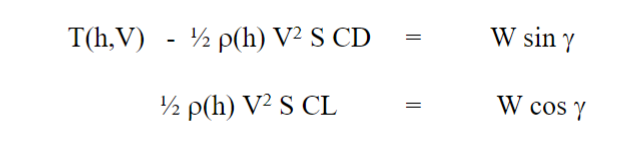

Find Level Flight Envelope using methods in G02EX2. 

%Guessing Clb
%Change the altitude according to the set altitude
guess1 = [0.1, 50];
sol1 = fsolve(@(var) levelflight(var, 0), guess1);
Clb = sol1(1);
v1 = sol1(2);

%Guessing Cla
%Change the altitude according to the set altitude
guess2 = [2, 10];
sol2 = fsolve(@(var) levelflight(var, 0), guess2);
Cla = sol2(1);
v2 = sol2(2);

function F = levelflight(var, h)
clg = var(1);
vg = var(2);
S = 17.1;
mass = 1248.5;
pset = 0.5;
Tsl = 288;
T = Tsl - 6.51 * (h/1000);
W = 9.81 * mass;

%Calculating Speed of Sound
a = sqrt(1.4 * 287 * T);

%Calculating Thrust
c0 = 7106.47 - 0.781351 * h;
c1 = -2094.99 + 0.216186 * h;
c2 = -3638.48 + 0.45727 * h;

T = pset * (c0 + (vg/a) * (c1 + c2 * (vg/a)));

%Equations to solve
F(1) = 0.5*clg*P2(h/1000)*vg^2*S - W;
F(2) = 0.5*(0.036 + 0.06 * clg^2)*P2(h/1000)*vg^2*S - T;
end
function F2 = climbflight(var, CL)
gamma = var(1);
velocity = var(2);

h = 0; %change according to the set altitude
S = 17.1;
mass = 1248.5;
pset = 0.5;
Tsl = 288;
T = Tsl - 6.51 * (h/1000);
W = 9.81 * mass;

%Calculating Speed of Sound
a = sqrt(1.4 * 287 * T);

%Calculating Thrust
c0 = 7106.47 - 0.781351 * h;
c1 = -2094.99 + 0.216186 * h;
c2 = -3638.48 + 0.45727 * h;

T = pset * (c0 + (velocity/a) * (c1 + c2 * (velocity/a)));

%Equations to solve
F2(1) = T - 0.5*(0.036 + 0.06 * CL^2)*P2(h/1000)*(velocity^2)*S - W * sin(gamma);
F2(2) = 0.5*CL*P2(h/1000)*(velocity^2)*S - W * cos(gamma);

end

Generate Climb Envelope by calculating with different values of CL in the range. For each CL, there will be a different Rate of Climb, Velocity and Climb Angle.

Rate of climb (ROC): $\frac{\textrm{dh}}{\textrm{dt}}=\frac{V\left(T-D\right)}{W}$

Climb Angle ($\gamma$): $\sin \;\gamma =\frac{\left(T-D\right)}{W}$

RC = [];
lv = [];
lgamma =[];
guess3 = [pi/180, 30];
%Generating the climb envelope
for CL = Clb:0.01:min(Cla,CLm)
    sol3 = fsolve(@(var) climbflight(var, CL), guess3);
    guess3 = [sol3(1), sol3(2)];
    disp(guess3);
    RC = [RC; sol3(2) * sin(sol3(1))];
    lv = [lv; sol3(2)];
    lgamma = [lgamma; sol3(1)];
end

Find maximum Rate of Climb and corresponding Velocity by finding local maximum. Need to interpolate the results from fsolve, revert the sign, then use fminsearch to obtain the maximum ROC.

fiminsearch: 

input1: function of the graph

input2: initial guess of the value(s).

%Calculating the maximum climb rate
spline_interp = spline(lv, RC);
f_to_minimize = @(x) -ppval(spline_interp, x);
x_max = fminsearch(f_to_minimize, 50); %Velocity
y_max = -f_to_minimize(x_max); % Max ROC

Find maximum Climb Angle. We already have a array of gamma.

%Calculating steepest climb angle
g1_max = max(lgamma); %Radian 
g1_max_deg = g1_max*(180/pi);

For each height their will be a different maximum flight envelope, hence different ROC. 

**Run the above fsolve for different altitude to have all values of Maximum ROC with Altitude.**

guess4 = [pi/180, 30];
for h = 0:100:5979
    lv1 = []; %New list for velocity at particular height
    RC1 = []; %New list for RC at particular height
    lg1 = []; %New list for gamma at particular height
    for CL = Clb:0.1:min(Cla, CLm)
        sol4 = fsolve(@(var) climbflight2(var, CL, h), guess4);
        guess4 = [sol4(1), sol4(2)];
        lv1 = [lv1, sol4(2)];
        RC1 = [RC1; sol4(2) * sol4(1)];
        lg1 = [lg1; sol4(1)];       
    end
    %Calculating the maximum climb rate
    spline_interp1 = spline(lv1, RC1);
    f_to_minimize = @(x) -ppval(spline_interp1, x);
    x_max = fminsearch(f_to_minimize, 50);
    RC_max = -f_to_minimize(x_max);
    lh = [lh; h];
    RCm = [RCm; RC_max];
    %Calculating steepest climb angle
    g_max = max(lg1); %Radian 
    g_max_deg = g_max*(180/pi); %Degree
    lg = [lg; g_max_deg];
end

Interpolate all pairs of (Altitude, ROC) using spline method. This output a set of y values (yq). Then can plot xq (x value of query points) against yq (y values of query points).

figure(2)
plot(RCm, lh);
hold on;
xq = [0.7; 0.6 ; 0.5; 0.4; 0.3; 0.2; 0.1]; 
yq = interp1(RCm, lh, xq, 'spline');
plot(xq,yq);

Extend the rest of line all the way to Absolute Ceiling (Zero ROC). Use interpolation as well since it's not a straight line.

y_service = interp1(RCm, lh, 0.503); %Height of service ceiling
xline(0.503);
hold off;
text(0.5,5661.3,'\leftarrow Service Ceiling');
%Add labels
xlabel('Rate of Climb (m/s)');
ylabel('Altitude (h)');

Calculate Flight Time.

Include the 'rest of the line' and interpolate together.

%Calculating the flight time
RC1 = [RCm ; xq];
HSC = [lh ; yq]; 
pp = spline(RC1, HSC);

Find the Service Ceiling altitude at specific ROC value (30.5m/min), yatintersect. This determines the range of ROC that aircraft operates.

%RC at service ceiling is 100 ft/min (30.5m/min), (0.5083m/s)
RC_ceil = 0.5083;
yatintersect = ppval(pp,RC_ceil);
disp(yatintersect);

We have values of altitude only. Therefore, integration should be from h = 0 to h = service ceiling. 

Since the integration range is altitude, we swap the x-y axis by having a new interpolation. Here the spline change the order of two input. 

To have the math correct, revert the ROC so becomes 1./ppval(pp1,z). Now is integrate1/ROC (s/m) over altitude (m), gives us time (s) after integration.

pp1 = spline(HSC,RC1);
yinterpolated = integral(@(z) (1./ppval(pp1,z)), 0, yatintersect);
ytime = yinterpolated/60; %convert to minutes

### Turning Flight (G02EX04)

Find level flight envelope for a given altitude. In this case, sea level.

function F1 = levelflight(var, h)

cl1 = var(1);
v1 = var(2); 

S = 17.1;
m = 1248.5;
pset = 0.5;
[rho, temp] = P2(h/1000);

%Calculating speed of sound
a = sqrt(1.4 * 287 * temp);

%Calculating Thrust
c0 = 7106.47 - 0.781351 * h;
c1 = -2094.00 + 0.216186 * h;
c2 = -3638.48 + 0.45727 * h;
T = pset * (c0 + v1/a * (c1 + c2 * (v1/a)));s

%Equations to solve
F1(1) = T - 0.5*rho*v1^2*S*(0.036 + 0.06 * cl1^2);
F1(2) = 0.5*rho*v1^2*S*cl1 - m*9.81;
end

Solve the flight envelope and find the range of CL. Put in initial guess for CL and velocity.

%Guessing clb
%Change the altitude according to the set altitude
guess1 = [0.1, 50];
sol1 = fsolve(@(var) levelflight(var, 0), guess1, options);
clb = sol1(1);
vb = sol1(2);

%Guessing Cla
%Change the altitude according to the set altitude
guess2 = [2, 10];
sol2 = fsolve(@(var) levelflight(var, 0), guess2, options);
cla = sol2(1);
va = sol2(2);


$$\begin{array}{l}
T\left(h,V\right)=0\ldotp 5*\mathrm{density}\left(h\right)*V^2 *S*\mathrm{CD}\\
W=\;0\ldotp 5*\mathrm{density}\left(h\right)*V^2 *S*\mathrm{CL}*\cos \mu \\
\mathrm{mV}\omega =0\ldotp 5*\mathrm{density}\left(h\right)*V^2 *S*\mathrm{CL}*\sin \mu 
\end{array}$$


Three equations with five unkowns. For a given altitude (h), iterate over different CL, it should then solve all other 3 unknowns.

function F2 = turningflight(var, cl)
miu1 = var(1); %Bank angle
v2 = var(2);   %Velocity
h = 0;
S = 17.1;
m = 1248.5;
pset = 0.5;
[rho, temp] = P2(h/1000);
%Calculating speed of sound
a = sqrt(1.4 * 287 * temp);
%Calculating Thrust
c0 = 7106.47 - 0.781351 * h;
c1 = -2094.00 + 0.216186 * h;
c2 = -3638.48 + 0.45727 * h;
T = pset * (c0 + v2/a * (c1 + c2 * (v2/a)));
%Equations to solve
F2(1) = T - 0.5*rho*v2^2*S*(0.036 + 0.06 * cl^2);
F2(2) = 0.5*rho*v2^2*S*cl*cos(miu1) - m*9.81;
end

Solve the turn envelope. For fsolve, initial guess is one degree of bank angle and minimum velocity in the range as provided by the level flight envelope.

%Generating turn envelope
pt = 285; %Number of iteration points
cln = linspace(clb, min(cla, clm), pt);
A = zeros(pt,5); %Generating nx5 array

guess3 = [pi/180, vb];
for i = 1:pt
  sol3 = fsolve(@(var) turningflight(var, cln(i)), guess3, options);
  [rho, temp] = P2(0/1000);
  w = (0.5*rho*sol3(2)^2*S*cln(i)*sin(sol3(1)))/ (m * sol3(2)); %turn rate
  L = 0.5*rho*sol3(2)^2*S*cln(i); %Lift
  R = sol3(2)/w;
  A(i, 1) = sol3(1); %bank angle
  A(i, 2) = sol3(2); %velocity
  A(i, 3) = w * (180/pi); %Change the turn rate to deg/s
  A(i, 4) = L; %Lift
  A(i, 5) = R; %Turn radius
  guess3 = [sol3(1), sol3(2)]; %update the new guess inputs to update fsolve
end

Plot the 5D array for the relationship we want. Here, Turn rate versus velocity.

figure(1)
plot(A(:,2) , A(:,3),'DisplayName', sprintf('Turn Envelope'));
title('Sea Level Turn Envelope');
xlabel('Velocity (m/s)');
ylabel('Omega (deg/s)');
hold on

Base on the graph, find local maximum to have maximum turn rate, and corresponding velocity.

Reverse the function to apply fminsearch(find local minimum). Then using the x value we obtain to find the actual y value.

%Maximum turn rate
pp = spline(A(:,2) , A(:,3));
func = @(x) -ppval(pp, x);
xmax = fminsearch(func, 50); % x value when local minimum is at
tmax = ppval(pp, xmax);

According to the results from fsolve, minimum turn radius can be found in the array of R.

%Smallest turn radius
rmin = min(A(:,5));
index = find(A(:,5) == rmin); 
vrmin = A(index, 2);
wrmin = A(index, 3);

Find maximum load factor. Load factor is given by:


$$n=\frac{L}{W}=\frac{1}{\cos \mu }$$


%Largest load factor
lmax = max(A(:,4));
nmax = lmax/(m*9.81);% find max load factor


Find velocity and turn rate at maximum load factor

index2 = find(A(:,4) == lmax); 
vlmax = A(index2, 2); 
wlmax = A(index2, 3); 

%Plotting the load factor line
nline = zeros(pt,2);
Vn = linspace(10, 100, pt); %List of velocities
n = 3;
L = 3*9.81*m;
for n = 1.5:0.5:Nm
    for i = 1:pt
        wn = (9.81/Vn(i)) * sqrt(n^2 -1);
        nline(i, 1) = wn * (180/pi); %Change to deg/s for turn rate
        nline(i, 2) = Vn(i);
    end
    
    plot(nline(:, 2), nline(:, 1),'.-', 'DisplayName', sprintf('Load factor =  %.1f', n));
end

Plot different turn radius curves.

%Plot line of different turn radius
for R = 40:50:300
    wlist = [];
    Vlist = [];
    for V = 10:100
        w = (180/pi)*V/R;
        wlist = [wlist,w];
        Vlist = [Vlist,V];
    end
    hold on
    plot(Vlist,wlist,":",'DisplayName',sprintf('Turn Radius = %.1f m',R));
end

Find the range of possible load factor. This will be used to plot different load factor curves.

pt2 = 500; %Number of iteration points
Vn2 = linspace(10, 100, pt2);
Lm = zeros(pt2, 1);
[rho, temp] = P2(0/1000);
nm = zeros(pt2, 1);
for j = 1:pt2
    Lm(j,1) = 0.5*rho*Vn2(j)^2*S*clm;
    nm(j,1) = Lm(j,1)/(m*9.81);
end

Using the obtained range of load factors, plot different load factor curves. For different load factor, an array of turn rate versus velocity can be calculated.


$$w=\frac{g}{V*\sqrt{n^2 -1}}$$


n3line = zeros(pt2,2);
for k = 1:pt2
    if (nm(k,1))^2 < 1 %make sure n^2 >1 so equation is valid
        continue
    else
        w3 = (9.81/Vn2(k)) * sqrt((nm(k,1))^2 -1); %find turn rate using above equation
    n3line(k, 1) = w3 * (180/pi); % turn rate %Change to deg/s for turn rate
    n3line(k, 2) = Vn2(k);%velocity
    end
end
plot(n3line(:,2) , n3line(:,1), '--r', 'DisplayName', sprintf('CL = %.1f', clm));
xlim([0, 100]);
ylim([0, 60]);

Find the corner speed and turn rate from the intersection

[vcorner, tcorner] = polyxpoly(n3line(:,2), n3line(:,1), nline(:,2), nline(:,1));
text(vcorner, tcorner, '\leftarrow Turn Rate at Corner Speed');

Find excess power by finding Thrust and Drag. T-D gives the remained force.

%Calculating speed of sound
a = sqrt(1.4 * 287 * temp);

%Calculating Thrust
c0 = 7106.47 - 0.781351 * 0; 
c1 = -2094.00 + 0.216186 * 0;
c2 = -3638.48 + 0.45727 * 0;
T1 = pset * (c0 + vcorner/a * (c1 + c2 * (vcorner/a)));
D1 = 0.5*rho*(vcorner)^2*S*(0.036 + 0.06 * clm^2);
Px = vcorner*(T1 - D1)/(m*9.81);